# II. Discrete Wavelet Transform

## 2.4. Signal Compression with DWT 

load('ECGsig.mat'); % loading data
fs = 257; % sampling frequency

ecg_sig = aVR;


### Compression with haar wavelet


[C_haar,L_haar] = wavedec(ecg_sig,10,'haar'); % wavelet coefficients and lengths of each level
 
% Calculating absolute values for sorting
coeff_magnitudes_haar = abs(C_haar); 

% Sorting the coefficients
sorted_coeffs_haar = sort(coeff_magnitudes_haar, 'descend');

% Total energy calculation for comparision
total_energy_haar = sum(sorted_coeffs_haar.^2);

% To identify the location of 99% energy
cumulative_energy_haar = cumsum(sorted_coeffs_haar.^2) / total_energy_haar;

% Identifying the coeeficient location of 99% energy
num_coeffs_haar = find(cumulative_energy_haar >= 0.99, 1);


disp(['No. of coefficients: ', num2str(num_coeffs_haar), ' out of ', num2str(length(C_haar)), ' coefficients.']);

No. of coefficients: 177 out of 2577 coefficients.


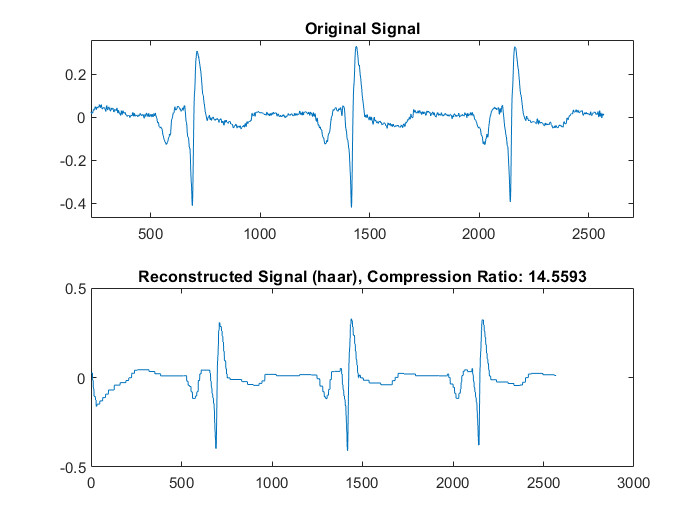


% Removal of coefficients below threshold
compressed_C_haar = C_haar;
compressed_C_haar(abs(C_haar) < sorted_coeffs_haar(num_coeffs_haar)) = 0;

% Reconstructing the signal with the thresholded coefficients
reconstructed_signal_haar = waverec(compressed_C_haar, L_haar, 'haar');

% Calculate compression ratio
compression_ratio_haar = length(C_haar)/num_coeffs_haar;

% Plot original vs reconstructed signals

figure;

subplot(2,1,1);
plot(ecg_sig); title('Original Signal');

subplot(2,1,2);
plot(reconstructed_signal_haar); title(['Reconstructed Signal (haar), Compression Ratio: ', num2str(compression_ratio_haar)]);

### Compression with db9 wavelet


[C_db9,L_db9] = wavedec(ecg_sig,10,'db9'); % wavelet coefficients and lengths of each level

% Calculating absolute values for sorting
coeff_magnitudes_db9 = abs(C_db9); 

% Sorting the coefficients
sorted_coeffs_db9 = sort(coeff_magnitudes_db9, 'descend');

% Total energy calculation for comparision
total_energy_db9 = sum(sorted_coeffs_db9.^2);

% To identify the location of 99% energy
cumulative_energy_db9 = cumsum(sorted_coeffs_db9.^2) / total_energy_db9;

% Identifying the coeeficient location of 99% energy
num_coeffs_db9 = find(cumulative_energy_db9 >= 0.99, 1);

disp(['No. of coefficients: ', num2str(num_coeffs_db9), ' out of ', num2str(length(C_db9)), ' coefficients.']);

No. of coefficients: 170 out of 2733 coefficients.


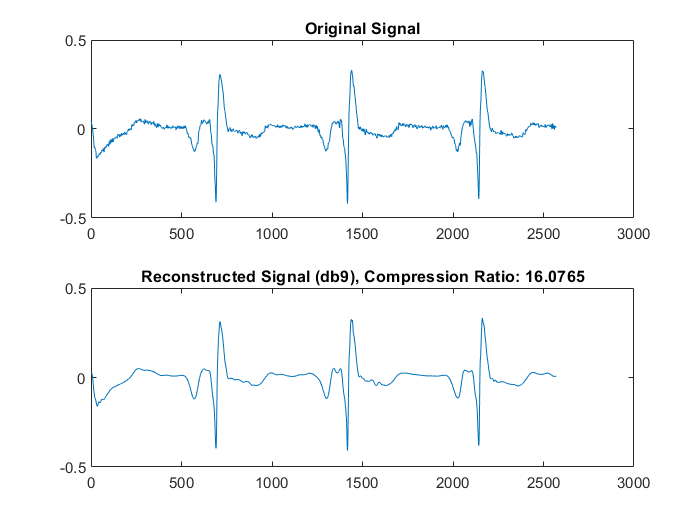


% Removal of coefficients below threshold
compressed_C_db9 = C_db9;
compressed_C_db9(abs(C_db9) < sorted_coeffs_db9(num_coeffs_db9)) = 0;

% Reconstructing the signal with the thresholded coefficients
reconstructed_signal_db9 = waverec(compressed_C_db9, L_db9, 'db9');

% Calculate compression ratio
compression_ratio_db9 = length(C_db9)/num_coeffs_db9;

% Plot original vs reconstructed signals

figure;

subplot(2,1,1);
plot(ecg_sig); title('Original Signal');

subplot(2,1,2);
plot(reconstructed_signal_db9); title(['Reconstructed Signal (db9), Compression Ratio: ', num2str(compression_ratio_db9)]);

% Saving coefficients to observe impact of compression

save('original_wav_coeff_of_ECG.mat', 'C_haar'); 
save('compressed_wav_coeff_of_ECG_haar.mat', 'compressed_C_haar');
save('compressed_wav_coeff_of_ECG_db9.mat', 'compressed_C_haar');
